clear
clc
rng default  
mpath = matlab.desktop.editor.getActiveFilename; 
[pathstr,~]=fileparts(mpath);
cd(pathstr); 

imgDir = fullfile("E:/MATLAB/Dataset/matlab_data/");
dataSet = imageDatastore(imgDir, 'IncludeSubfolders', true, 'LabelSource', 'foldernames');
trainSetDetail = countEachLabel(dataSet) % 训练数据

trainSetDetail = 10×2 table
          Label          Count
    _________________    _____

    apple_pie             328 
    baby_back_ribs        400 
    baklava               400 
    beef_carpaccio        400 
    beef_tartare          400 
    beet_salad            400 
    beignets              400 
    bibimbap              400 
    bread_pudding         400 
    breakfast_burrito     400 


设置划分后的数据集路径，包括训练集、验证集、测试集

% 划分数据集
[trainData, valData, testData] = splitEachLabel(dataSet, 0.6, 0.2, 'randomize');

% 创建保存图像的目录
trainDir = fullfile(pathstr, 'TrainingSet');
valDir = fullfile(pathstr, 'ValidationSet');
testDir = fullfile(pathstr, 'TestSet');

if ~exist(trainDir, 'dir')
    mkdir(trainDir);
end

if ~exist(valDir, 'dir')
    mkdir(valDir);
end

if ~exist(testDir, 'dir')
    mkdir(testDir);
end

% 复制训练数据集图像
for idx = 1:numel(trainData.Files)
    currentImgPath = trainData.Files{idx};
    [~, imgBaseName, imgExt] = fileparts(currentImgPath);
    destinationPath = fullfile(trainDir, [imgBaseName, imgExt]);
    copyfile(currentImgPath, destinationPath);
end

% 复制验证数据集图像
for idx = 1:numel(valData.Files)
    currentImgPath = valData.Files{idx};
    [~, imgBaseName, imgExt] = fileparts(currentImgPath);
    destinationPath = fullfile(valDir, [imgBaseName, imgExt]);
    copyfile(currentImgPath, destinationPath);
end

% 复制测试数据集图像
for idx = 1:numel(testData.Files)
    currentImgPath = testData.Files{idx};
    [~, imgBaseName, imgExt] = fileparts(currentImgPath);
    destinationPath = fullfile(testDir, [imgBaseName, imgExt]);
    copyfile(currentImgPath, destinationPath);
end


从训练图像数据集中随机抽取并显示 16 张图像进行查看

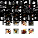

numTrainImages = numel(trainData.Labels);
idx = randperm(numTrainImages,16);
figure
for i = 1:16
    subplot(4,4,i)
    I = readimage(trainData,idx(i));
    imshow(I)
    title(trainData.Labels(idx(i)))
end

加载预训练模型

net = resnet50;
layers = net.Layers

layers =   具有以下层的 177×1 Layer 数组:

     1   'input_1'                      图像输入         224×224×3 图像: 'zerocenter' 归一化
     2   'conv1'                        二维卷积         64 7×7×3 卷积: 步幅 [2  2]，填充 [3  3  3  3]
     3   'bn_conv1'                     批量归一化        批量归一化: 64 个通道
     4   'activation_1_relu'            ReLU            ReLU
     5   'max_pooling2d_1'              二维最大池化      3×3 最大池化: 步幅 [2  2]，填充 [1  1  1  1]
     6   'res2a_branch2a'               二维卷积         64 1×1×64 卷积: 步幅 [1  1]，填充 [0  0  0  0]
     7   'bn2a_branch2a'                批量归一化        批量归一化: 64 个通道
     8   'activation_2_relu'            ReLU            ReLU
     9   'res2a_branch2b'               二维卷积         64 3×3×64 卷积: 步幅 [1  1]，填充 'same'
    10   'bn2a_branch2b'                批量归一化        批量归一化: 64 个通道
    11   'activation_3_relu'            ReLU            ReLU
    12   'res2a_branch2c'               二维卷积         256 

inputSize = net.Layers(1).InputSize  % 网络输入尺寸

inputSize =    224   224     3


`下面代码的第一个 10` 是新全连接层的输出节点数量，意思就是数据集中的类别数量，因为我有10个类别，大概根据自己的数据集进行修改。`'WeightLearnRateFactor',10` 和 `'BiasLearnRateFactor',10` 设置权重和偏置的学习率因子为 10，意思就是这些参数在训练过程中将比默认学习率快 10 倍更新。

lgraph = layerGraph(net); 
newLearnableLayer = fullyConnectedLayer(10, ...
    'Name','new_fc', ...
    'WeightLearnRateFactor',10, ...
    'BiasLearnRateFactor',10);

lgraph = replaceLayer(lgraph,'fc1000',newLearnableLayer);
newClassLayer = classificationLayer('Name','new_classoutput');
lgraph = replaceLayer(lgraph,'ClassificationLayer_fc1000',newClassLayer);

为了提高模型的泛化能力，我们在训练过程中使用数据增强技术。数据增强可以通过对训练图像进行随机变换（例如翻转、平移等）来生成更多的训练样本。这有助于模型在面对不同视角、尺度和形态的图像时具有更好的泛化能力。在本例中，采用随机水平翻转以及随机平移的方法进行数据增强。此外，还需要处理灰度图像。由于预训练的 ResNet-50 模型期望输入为彩色图像，需要将灰度图像转换为伪彩色图像，使其可以被模型正确处理。

pixelRange = [-30 30];
imageAugmenter = imageDataAugmenter( ...
    'RandXReflection',true, ...
    'RandXTranslation',pixelRange, ...
    'RandYTranslation',pixelRange);
augimdsTrain = augmentedImageDatastore(inputSize(1:2),trainData, ...
   'DataAugmentation',imageAugmenter,'ColorPreprocessing','gray2rgb');
augimdsValidation = augmentedImageDatastore(inputSize(1:2),valData);
augimdsTest = augmentedImageDatastore(inputSize(1:2),testData);

options = trainingOptions('sgdm', ...
    'MiniBatchSize',32, ...
    'MaxEpochs',2, ...
    'InitialLearnRate',1e-4, ...
    'Shuffle','every-epoch', ...
    'ValidationData',augimdsValidation, ...
    'ValidationFrequency',3, ...
    'Verbose', true, ...
    'Plots','training-progress');

model = trainNetwork(augimdsTrain,lgraph,options);

在单 GPU 上训练。
正在初始化输入数据归一化。
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　轮　　｜　　迭代　　｜　　　　经过的时间　　　　　｜　　小批量准确度　　｜　　验证准确度　　｜　　小批量损失　　｜　　验证损失　　｜　　基础学习率　　｜
｜　　　　　｜　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　｜　　　　　　　　　｜　　　　　　　　　｜　　　　　　　　｜　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　　１　｜　　　　１　｜　　　　　００：００：０４　｜　　　　３．１２％　｜　　　８．４１％　｜　　２．６５７０　｜　２．８１０２　｜　１．００００ｅ－０４　｜
｜　　　１　｜　　　　３　｜　　　　　００：００：０７　｜　　　　９．３８％　｜　　　８．０３％　｜　　２．５５４６　｜　２．７４０５　｜　１．００００ｅ－０４　｜


save('ResNet_4_classes.mat', 'model');

[YPred,scores] = classify(model, augimdsTest);
YTest = imdsTest.Labels;
accuracy = mean(YPred == YTest)